**Prueba de desempeño de las Tecnicas de calculo discreto de la transformada de fourier**

Establecimiento de parametros físicos del obstaculo que se quiere usar como ejemplo

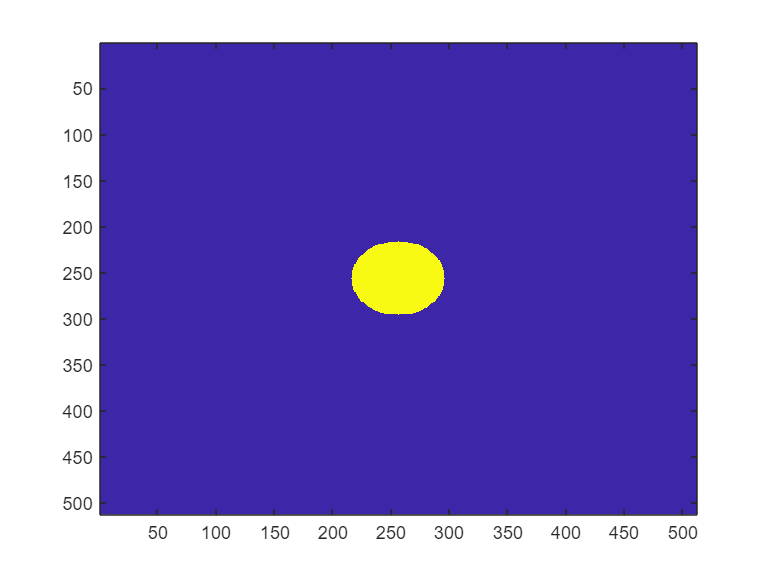

% Definición de parametros fisicos
um = 1E-6;
nm = 1E-9;
mm = 1E-3;

N = 512 ; % Numero de Pixeles de largo y ancho

dx = 0.5*um; % Distancia entre pixeles
dy = 0.5*um;

z = 0.5*mm;

lambda = 650*nm;

% Creación de la transmitancia en el plano z = 0
% El obstaculo corresponde a una pantalla con  agujero de 10*um de radio

radio = 20*um/dx; % tamaño del radio en pixeles, tamaño fisico = 2 um


transmitancia = filtroCircular([N/2 N/2],radio,[N N]);
imagesc(transmitancia)

Desempeño de difracción por espectro angular con DFT por medio de sumas discretas

tic
EA_campoPropagado = espectroAngular(transmitancia,dx,dy,z,lambda,"dft",true);
toc

Elapsed time is 3812.488647 seconds.


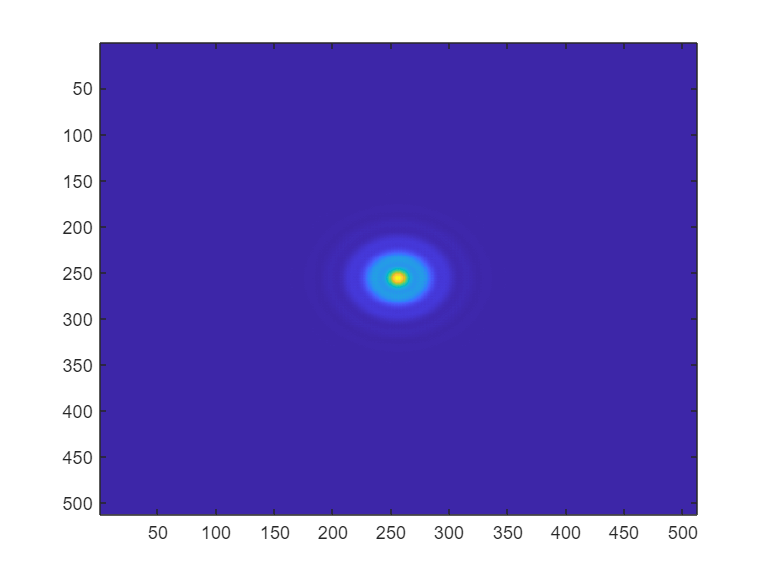

EA_intensidad = abs(EA_campoPropagado).^2;
imagesc(EA_intensidad)

Desempeño de difracción por espectro Angular con DFT por medio de transformadas rápidas de fourier FFT

tic
EA_campoPropagadoFFT = espectroAngular(transmitancia,dx,dy,z,lambda,"dft",false);
toc

Elapsed time is 0.018111 seconds.


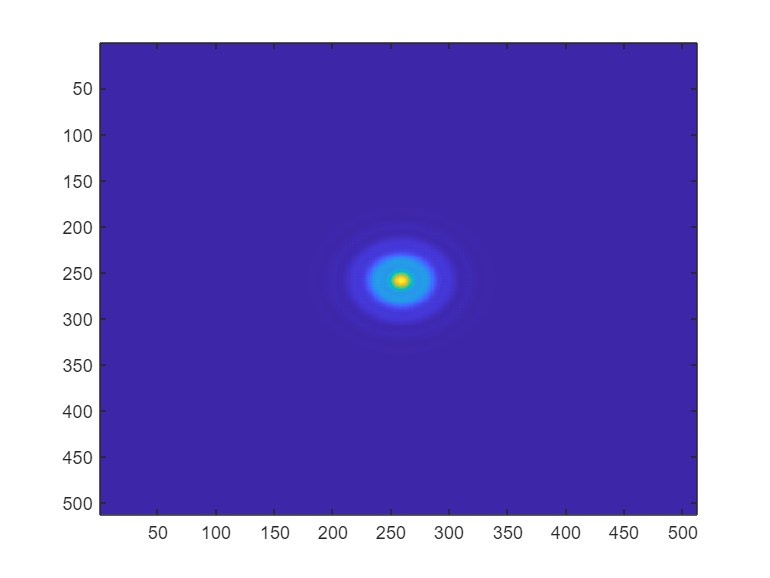

EA_intensidadFFT = abs(EA_campoPropagadoFFT).^2;
imagesc(EA_intensidadFFT)

Desempeño de difracción por transformada de fresnel con DFT por medio de sumas discretas

tic
TF_campoPropagado = transformadaFresnel(transmitancia,dx,dy,z,lambda,"dft",true,"zoom",true);
toc

Elapsed time is 1896.477588 seconds.


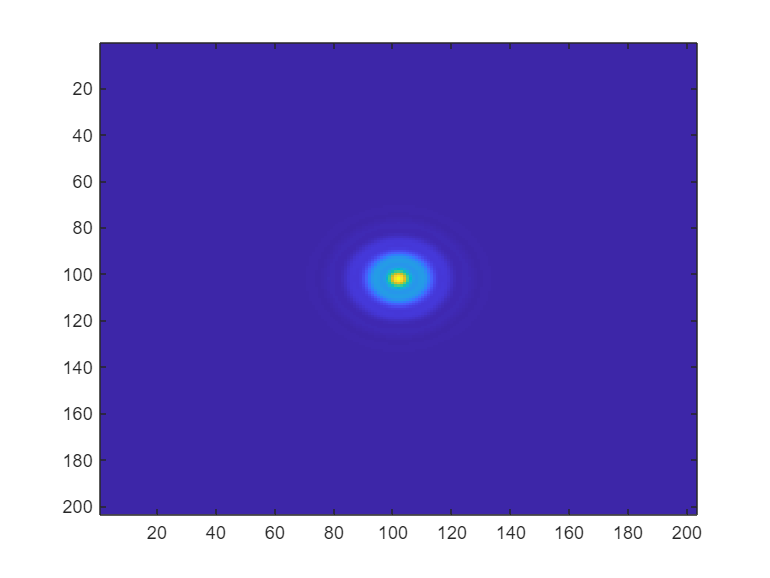

TF_intensidad = abs(TF_campoPropagado).^2;
imagesc(TF_intensidad)

Desempeño de difracción por transformada de fresnel con DFT por medio de transformadas rápidas de fourier FFT

tic
TF_campoPropagadoFFT = transformadaFresnel(transmitancia,dx,dy,z,lambda,"dft",false,"zoom",true);
toc

Elapsed time is 0.019140 seconds.


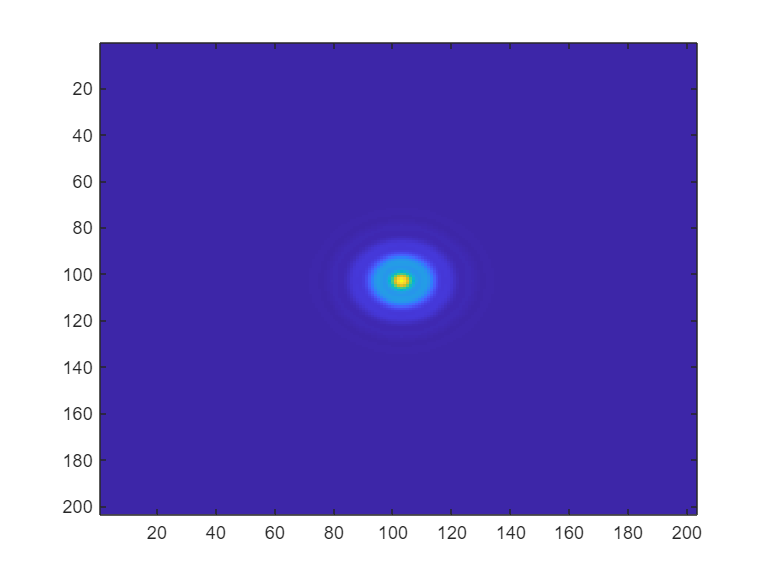

TF_intensidadFFT = abs(TF_campoPropagadoFFT).^2;
imagesc(TF_intensidadFFT)